syms x1 x2 x3 alpha u k1 k2 k3 l1 l2 l3 zeta real
syms s complex

## Suppose you have the following system

Consider the following state-space model for the azimuthal angle of a dish used to track a satellite, where $y$ is the azimuthal angle, $u$ is the input voltage to a power amplifier, used to drive the dish, and $x$ is the state of the system. 


$$\dot{x} = f(x,u) = Ax+Bu$$



$$y = Cx$$


x = [x1; x2; x3];
x1dot = x2;
x2dot = x3;
x3dot = -171*x2-101.71*x3+u

$$x3dot = u-171\,x_{2}-\frac{10171\,x_{3}}{100}$$

f = [x1dot; x2dot; x3dot]

$$f = \left(\begin{array}{c} x_{2}\\ x_{3}\\ u-171\,x_{2}-\frac{10171\,x_{3}}{100} \end{array}\right)$$

y = 1325*x1

$$y = 1325\,x_{1}$$

% linearise about origin
A = subs(jacobian(f,x),{x1 x2 x3 u},{0 0 0 0})

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & -171 & -\frac{10171}{100} \end{array}\right)$$

eig(A) % is open-loop system stable?

$$ans = \left(\begin{array}{c} -100\\ -\frac{171}{100}\\ 0 \end{array}\right)$$

B = subs(jacobian(f,u),{x1 x2 x3 u},{0 0 0 0})

$$B = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

C = subs(jacobian(y,x),{x1 x2 x3 u},{0 0 0 0})

$$C = \left(\begin{array}{ccc} 1325 & 0 & 0 \end{array}\right)$$

D = subs(jacobian(y,u),{x1 x2 x3 u},{0 0 0 0})

$$D = 0$$

process = ss(eval(A), eval(B), eval(C), eval(D),'InputName',{'u'}','OutputName','y','StateName',{'x1', 'x2', 'x3'})

process =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3       0    -171  -101.7
 
  B = 
       u
   x1  0
   x2  0
   x3  1
 
  C = 
        x1    x2    x3
   y  1325     0     0
 
  D = 
      u
   y  0
 
Continuous-time state-space model.



### Is the system reachable?

Wr = [B A*B A^2*B]

$$Wr = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 1 & -\frac{10171}{100}\\ 1 & -\frac{10171}{100} & \frac{101739241}{10000} \end{array}\right)$$

detWr = det(Wr)

$$detWr = -1$$

rankWr = rank(Wr)

rankWr = 3

reachableIff = not(simplify(detWr == 0))

$$reachableIff = \mathrm{symtrue}$$

## Is the system observable?

Wo = [C; C*A; C*A^2]

$$Wo = \left(\begin{array}{ccc} 1325 & 0 & 0\\ 0 & 1325 & 0\\ 0 & 0 & 1325 \end{array}\right)$$

rank(Wo)

ans = 3

detWo = det(Wo)

$$detWo = 2326203125$$

observableIff = not(simplify(detWo == 0))

$$observableIff = \mathrm{symtrue}$$

## Use the separation principle to derive the state feedback and observer gains for a dynamic output feedback controller that places all the poles at a desirable location

### Compute matrix $K$for a state feedback controller $u=-Kx$ to place e/values of state feedback closed-loop dynamics matrix$A-BK$at desired location

n = length(x) % number of states

n = 3

K = [k1 k2 k3]

$$K = \left(\begin{array}{ccc} k_{1} & k_{2} & k_{3} \end{array}\right)$$

ABK = A-B*K

$$ABK = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ -k_{1} & -k_{2}-171 & -k_{3}-\frac{10171}{100} \end{array}\right)$$

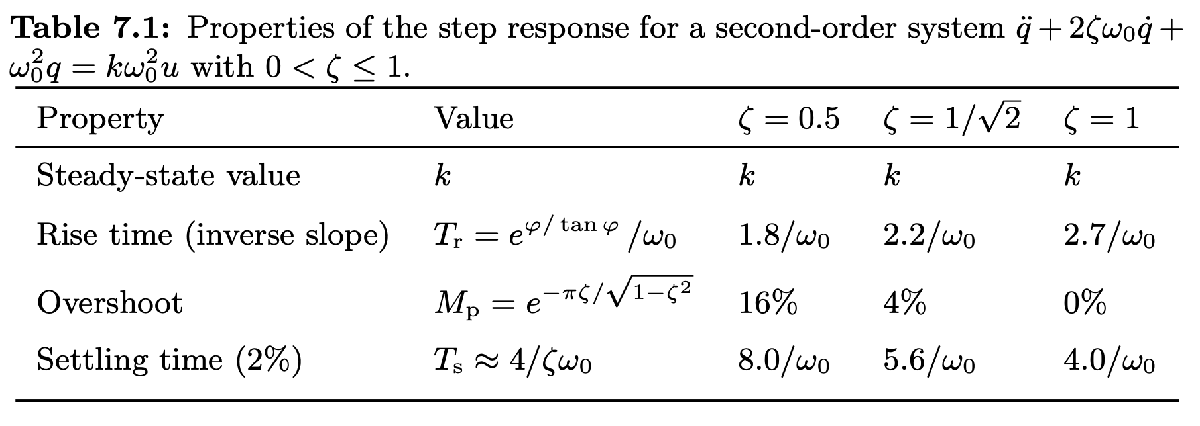

damp(process) % open-loop system

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.71e+00     1.00e+00       1.71e+00         5.85e-01    
 -1.00e+02     1.00e+00       1.00e+02         1.00e-02    


Mp = 0.1; % desired overshoot
Tsettle = 1; % desired 2% settling time
zeta = vpasolve(Mp == exp(-pi*zeta/sqrt(1-zeta^2)),zeta) % damping factor from table

$$zeta = 0.59115503379889750930516375129716$$

omega = 4/zeta/Tsettle % natural frequency from table

$$omega = 6.7664145127803188285017784634721$$

pdomc = s^2+2*zeta*omega*s+omega^2 % dominant pair 

$$pdomc = s^{2}+8.0\,s+45.784365358764119434931443500208$$

solve(pdomc==0,s) % check where the roots are and place third pole 10 times further from imaginary axis

$$ans = \left(\begin{array}{c} -4.0-5.4575054153673653899431345017254\,\mathrm{i}\\ -4.0+5.4575054153673653899431345017254\,\mathrm{i} \end{array}\right)$$

pdABK = expand((s+40)*pdomc) % desired characteristic polynomial for A-B*K where K is a state feedback

$$pdABK = s^{3}+48.0\,s^{2}+365.78436535876411943493144350021\,s+1831.3746143505647773972577400083$$

pABK = det(s*eye(n)-ABK) % actual characteristic polynomial for A-B*K where K is a state feedback

$$pABK = k_{1}+171\,s+k_{2}\,s+k_{3}\,s^{2}+\frac{10171\,s^{2}}{100}+s^{3}$$

coeffseqr = coeffs(pABK,s) == coeffs(pdABK,s) % equate coefficients

$$coeffseqr = \left(\begin{array}{cccc} k_{1}=1831.3746143505647773972577400083 & k_{2}+171=365.78436535876411943493144350021 & k_{3}+\frac{10171}{100}=48.0 & 1=1 \end{array}\right)$$

Ks = solve(coeffseqr,K,"ReturnConditions",true); % solve for K
Ks.conditions % conditions under which a solution exists

$$ans = \mathrm{symtrue}$$

K = [Ks.k1 Ks.k2 Ks.k3] 

$$K = \left(\begin{array}{ccc} 1831.3746143505647773972577400083 & 194.78436535876411943493144350021 & -53.71 \end{array}\right)$$

### Compute observer gain $L$ to place eigenvalues of state estimate error dynamics matrix$A-LC$

L = [l1; l2; l3]

$$L = \left(\begin{array}{c} l_{1}\\ l_{2}\\ l_{3} \end{array}\right)$$

ALC(L) = A-L*C

$$ALC(l1, l2, l3) = \left(\begin{array}{ccc} -1325\,l_{1} & 1 & 0\\ -1325\,l_{2} & 0 & 1\\ -1325\,l_{3} & -171 & -\frac{10171}{100} \end{array}\right)$$

% the desired transient response for the observer should have a 10%
% overshoot and a natural frequency 10 times greater than the closed-loop
% system with a state feedback control as computed above
pdomo = s^2+2*zeta*omega*10*s+(10*omega)^2 % dominant pair

$$pdomo = s^{2}+80.0\,s+4578.4365358764119434931443500208$$

solve(pdomo==0,s) % check where the roots are and place third pole 10 times further from imaginary axis

$$ans = \left(\begin{array}{c} -40.0-54.575054153673653899431345017254\,\mathrm{i}\\ -40.0+54.575054153673653899431345017254\,\mathrm{i} \end{array}\right)$$

pdALC = expand((s+400)*pdomo)  % desired characterisic polynomial for observer error dynamics

$$pdALC = s^{3}+480.0\,s^{2}+36578.436535876411943493144350021\,s+1831374.6143505647773972577400083$$

pALC = det(s*eye(n)-ALC) % actual characterisic polynomial for observer error dynamics

$$pALC(l1, l2, l3) = 226575\,l_{1}+\frac{539063\,l_{2}}{4}+1325\,l_{3}+171\,s+\frac{539063\,l_{1}\,s}{4}+1325\,l_{2}\,s+1325\,l_{1}\,s^{2}+\frac{10171\,s^{2}}{100}+s^{3}$$

coeffseqo = coeffs(pALC,s) == coeffs(pdALC,s) % equate coefficients

$$coeffseqo(l1, l2, l3) = \left(\begin{array}{cccc} 226575\,l_{1}+\frac{539063\,l_{2}}{4}+1325\,l_{3}=1831374.6143505647773972577400083 & \frac{539063\,l_{1}}{4}+1325\,l_{2}+171=36578.436535876411943493144350021 & 1325\,l_{1}+\frac{10171}{100}=480.0 & 1=1 \end{array}\right)$$

Ls = solve(coeffseqo,L,"ReturnConditions",true); % solve for L
Ls.conditions % conditions under which a solution exists

$$ans = \mathrm{symtrue}$$

L = [Ls.l1; Ls.l2; Ls.l3]

$$L = \left(\begin{array}{c} 0.28550188679245283018867924528302\\ -1.5610863125461041935900797358334\\ 1492.1267864721320140562792665417 \end{array}\right)$$

## **Compute expression for **observer-based controller

Compute a state space expression for an observer-based controller that has as its inputs $y$ and $r$ and 


$$u=-K\hat{x}+K_fr$$
 

as its output, where $r$ is a given constant reference signal and $\hat{x}$ is an estimate of the state. 

Compute the feedforward gain $K_f$ such that $\lim_{t\rightarrow \infty } y(t) = r$.

p = size(C,1) % number of measured outputs

p = 1

Kf = -(C*((A-B*K)\B))\eye(p)

$$Kf = 1.3821695202645771904884964075534$$

m = size(B,2); % number of control inputs
Acontrol = A-B*K-L*C;
Bcontrol = [L B*Kf];
Ccontrol = -K;
Dcontrol = [zeros(m,p) Kf];
controller  = ss(eval(Acontrol), eval(Bcontrol), eval(Ccontrol), eval(Dcontrol),'InputName',{'y','r'}','OutputName','u','StateName',{'xhat1', 'xhat2', 'xhat3'})

controller =
 
  A = 
               xhat1       xhat2       xhat3
   xhat1      -378.3           1           0
   xhat2        2068           0           1
   xhat3  -1.979e+06      -365.8         -48
 
  B = 
               y       r
   xhat1  0.2855       0
   xhat2  -1.561       0
   xhat3    1492   1.382
 
  C = 
       xhat1   xhat2   xhat3
   u   -1831  -194.8   53.71
 
  D = 
          y      r
   u      0  1.382
 
Continuous-time state-space model.



### Check that eigenvalues of closed-loop dynamics matrix are as desired

Closed-loop dynamics matrix with augmented state as$(x,\hat{x})$:

Aclxandxhat = [A -B*K; L*C A-B*K-L*C];

Closed-loop dynamics matrix with augmented state as$(x,\tilde{x})$, where $\tilde{x}=x-\hat{x}$:

Aclxandxtilde = [A-B*K B*K; zeros(n) A-L*C]; % block upper triangular

Check whether the eigenvalues of the two matrices above are the same and are all at the desired locations

eig(Aclxandxhat)

$$ans = \left(\begin{array}{c} -4.0+5.4575054153673653899431345017254\,\mathrm{i}\\ -4.0-5.4575054153673653899431345017254\,\mathrm{i}\\ -40.0\\ -40.0+54.575054153673653899431345017254\,\mathrm{i}\\ -40.0-54.575054153673653899431345017254\,\mathrm{i}\\ -400.0 \end{array}\right)$$

eig(Aclxandxtilde)

$$ans = \left(\begin{array}{c} -4.0+5.4575054153673653899431345017254\,\mathrm{i}\\ -4.0-5.4575054153673653899431345017254\,\mathrm{i}\\ -40.0\\ -40.0+54.575054153673653899431345017254\,\mathrm{i}\\ -40.0-54.575054153673653899431345017254\,\mathrm{i}\\ -400.0 \end{array}\right)$$

## Explore effect of a constant input disturbance

processdist = ss(eval(A), eval([B B]), eval(C), eval(D),'InputName',{'u', 'disturbance'},'OutputName','y','StateName',{'x1', 'x2', 'x3'})

processdist =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3       0    -171  -101.7
 
  B = 
                 u  disturbance
   x1            0            0
   x2            0            0
   x3            1            1
 
  C = 
        x1    x2    x3
   y  1325     0     0
 
  D = 
                u  disturbance
   y            0            0
 
Continuous-time state-space model.




clsys = connect(processdist,controller,{'r', 'disturbance'},{'y', 'u'});
[Acl,Bcl,Ccl,Dcl] = ssdata(clsys);
eig(Acl) % check whether closed-loop poles are the same as above

ans = 	1.0e+02 *

  -4.0000 + 0.0000i
  -0.4000 + 0.5458i
  -0.4000 - 0.5458i
  -0.4000 + 0.0000i
  -0.0400 + 0.0546i
  -0.0400 - 0.0546i


damp(processdist) % open-loop system

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.71e+00     1.00e+00       1.71e+00         5.85e-01    
 -1.00e+02     1.00e+00       1.00e+02         1.00e-02    


damp(clsys) % closed-loop system

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.00e+00 + 5.46e+00i     5.91e-01       6.77e+00         2.50e-01    
 -4.00e+00 - 5.46e+00i     5.91e-01       6.77e+00         2.50e-01    
 -4.00e+01                 1.00e+00       4.00e+01         2.50e-02    
 -4.00e+01 + 5.46e+01i     5.91e-01       6.77e+01         2.50e-02    
 -4.00e+01 - 5.46e+01i     5.91e-01       6.77e+01         2.50e-02    
 -4.00e+02                 1.00e+00       4.00e+02         2.50e-03    


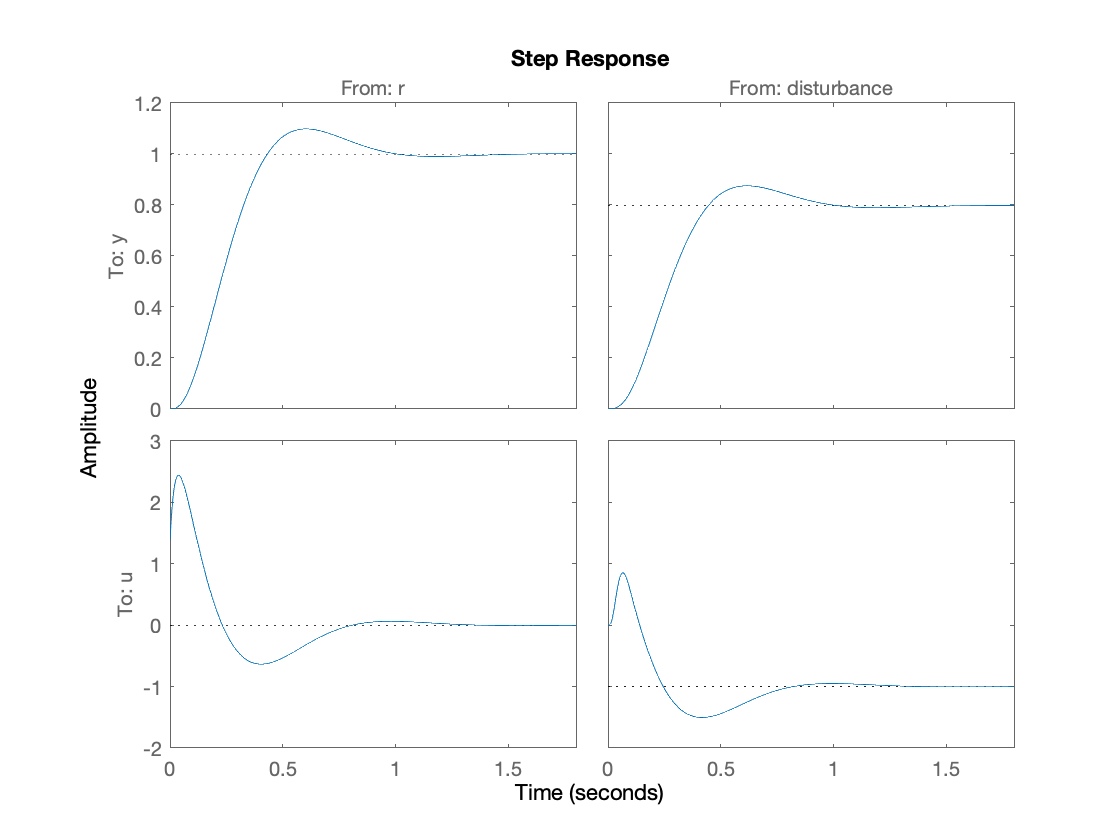

step(clsys) % closed-loop system

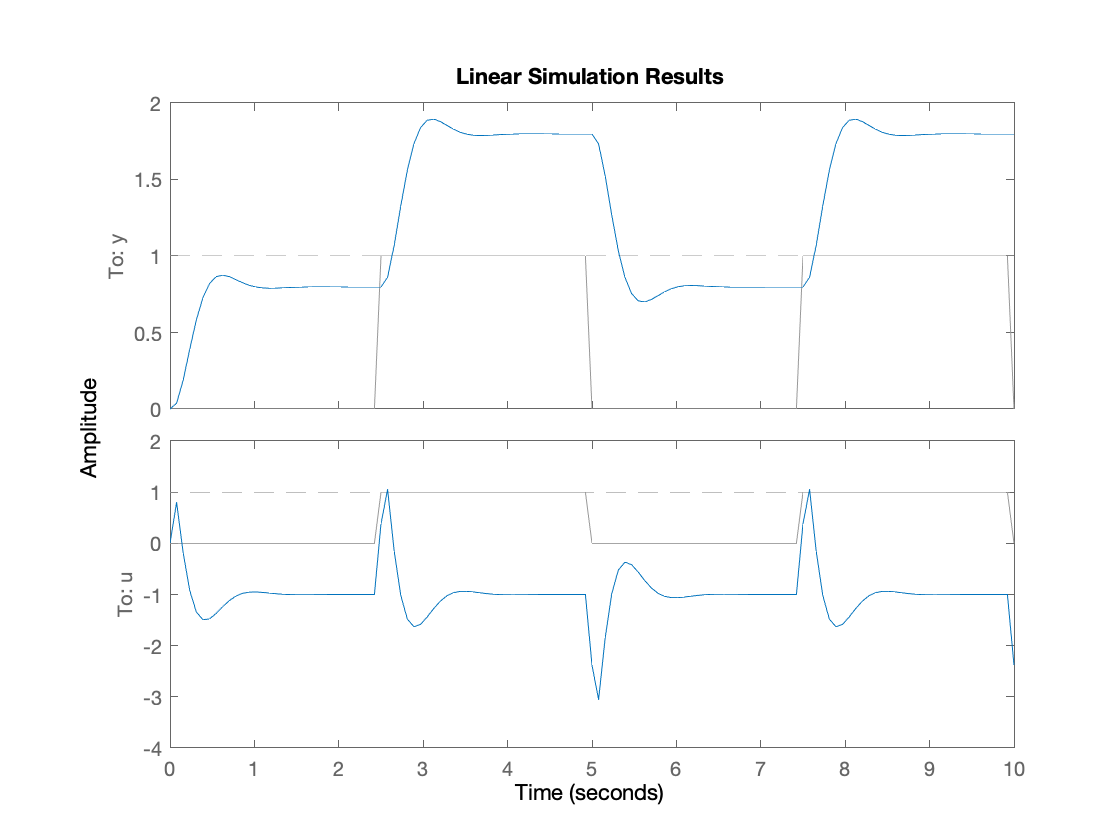

[sig,t] = gensig("square",5,10);
x0 = zeros(n,1);
lsim(clsys,[sig ones(length(t),1)],t,[x0; x0]) % no initial state estimate error, r = sig, d  = 1

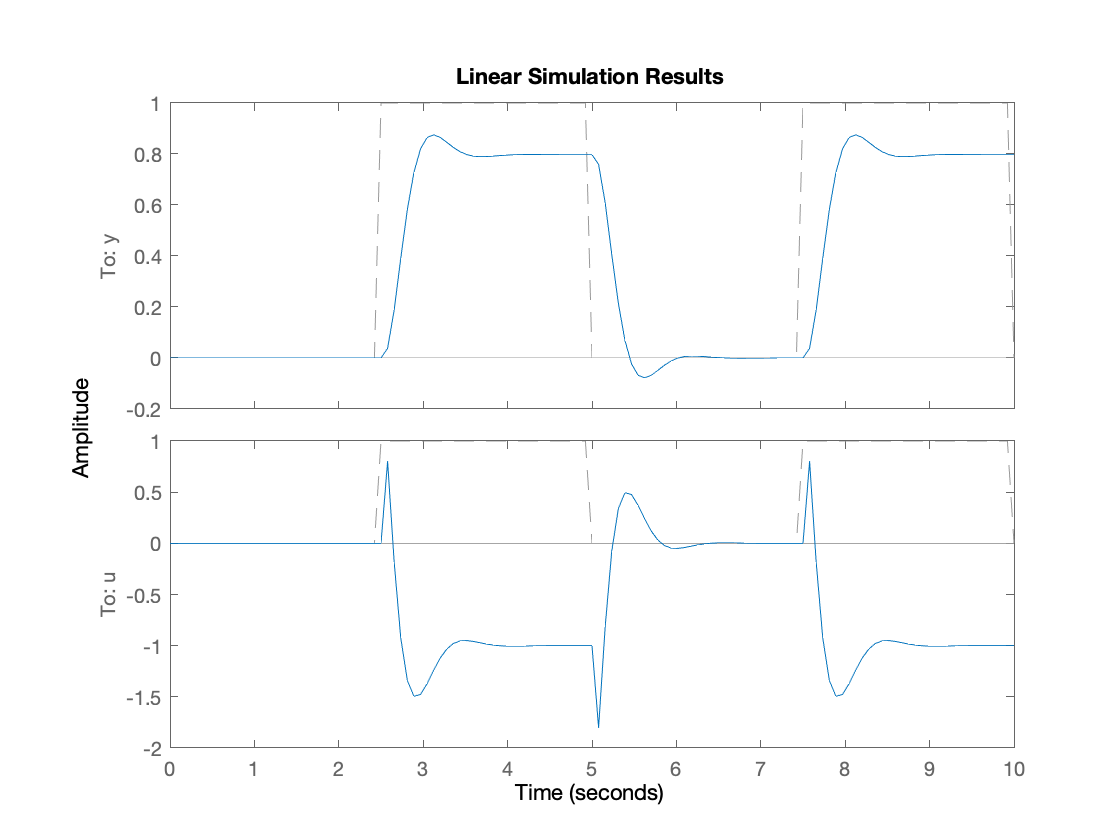

lsim(clsys,[0*sig sig],t,[x0; x0]) % no initial state estimate error, r = 0, d = sig

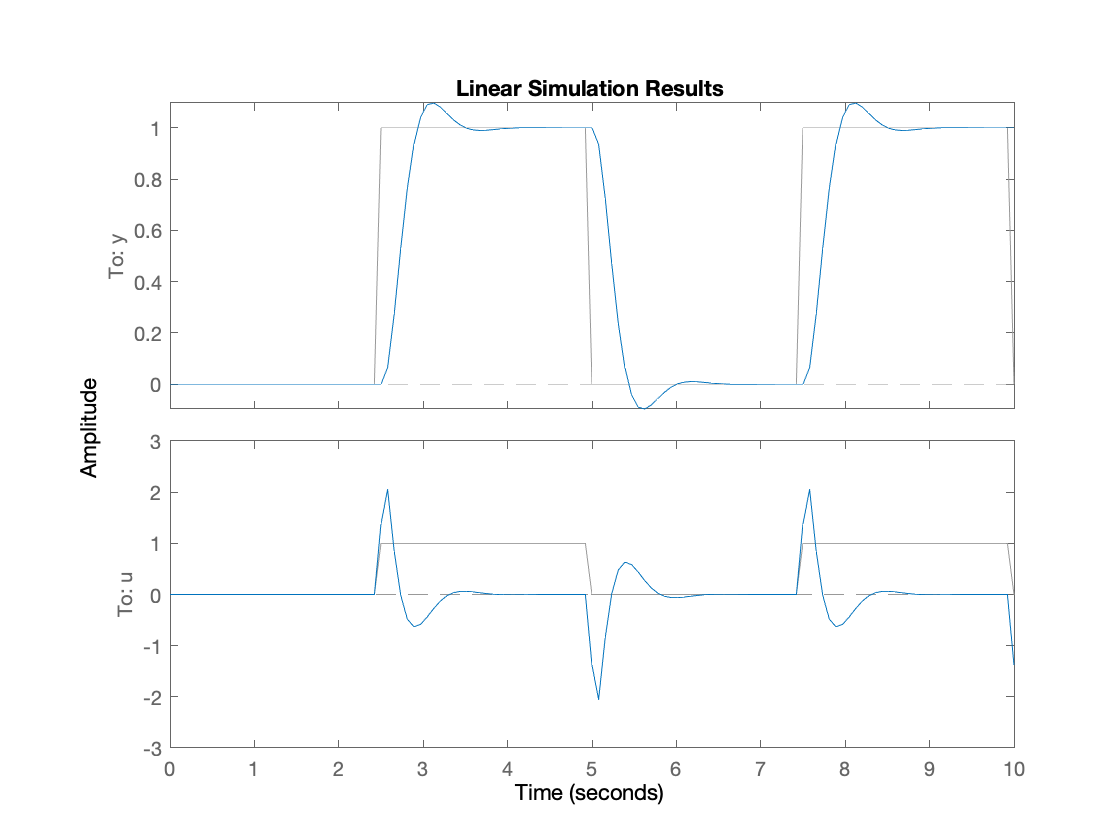

lsim(clsys,[sig 0*sig],t,[x0; x0]) % no initial state estimate error, r = sig, d  = 0